# 2D (non)-Cartesian SENSE demo 

This is a demo to play around with certain factors involved in the generalized iterative SENSE reconstruction. The simulations are based on radial imaging with uniform angular increments. The simulations are performed on the shepp-logan phantom or brain images.  MAKE SURE YOU ARE IN THE DIRECTORY: "/Sense_educational/" 

Tom Bruijnen 20170625

## Set input parameters for the simulations

All these parameters are adjustable, only NC & M have to be integers

% Empty workspace
clear all;clc;echo off
addpath(genpath(pwd))

% If you would rather have a brain image to look at set the parameter below to 1.
brain=0;

NC=4;           % Number of receive coils 
M=128;          % Matrix size of image 
csm_sigma=4.5;    % Width of gaussian coil sensitivity profiles
R=2;              % Undersampling factor 

% Some noise characteristics, note that these affect the results a lot
noise_sampling=.0005;         % Noise on samples % of kmax
noise_csm=.01;               % Noise on acquired csm % of Imax

% Check if input is correct
NC=round(NC);M=round(M);

## Create phantom and coil sensitivity maps

Create the phantom and coil sensitivity maps without any noise

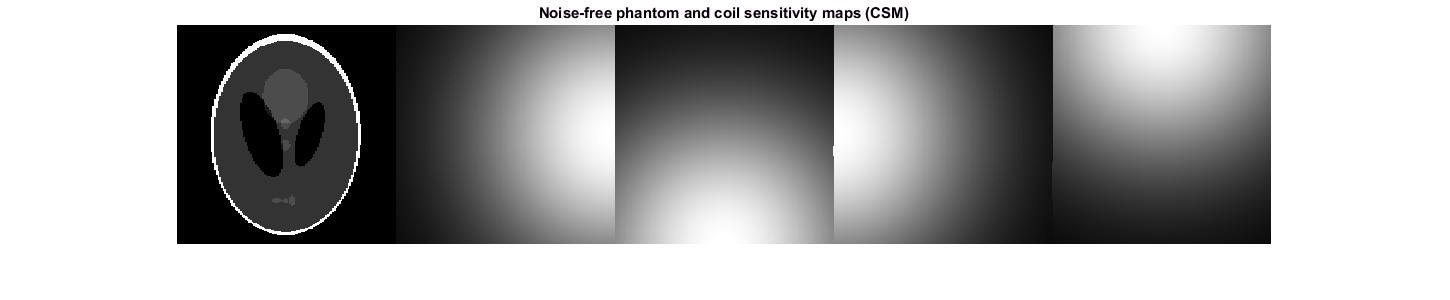

% Create shepp-logan phantom
x_true=phantom(M);

% If you wanted the brain phantom, do some interpolation 
if brain;load brain;[x1,y1]=meshgrid(1:512,1:512);[x2,y2]=meshgrid(1:M,1:M);
    x_true=interp2(x1,y1,abs(x_true),512/M*x2,512/M*y2,'spline');end

% Generate Gaussian shaped coil sensitivity maps
csm=generate_csm(NC,M,csm_sigma);

% Visualization
figure(1);imshow3(abs(cat(3,x_true,csm)),[],[1 (1+NC)]);
set(gcf,'Position',[0 0 1450 300]);
title('Noise-free phantom and coil sensitivity maps (CSM)');

## Why does the classical SENSE formalism NOT work for non-Cartesian sampling?

Lets examine the corresponding point-spread-function (PSF). Just like we did for the Cartesian case we mimic a experiment where we put ones on all our samples in k-space and mimic undersampling by entering zero values at specific radial lines. For non-Cartesian sampling we have two additional difficulties: (1): in order to transform the k-space samples from a non-Cartesian coordinate system to a Cartesian grid we have to perform interpolation. However, since convolution (interpolation) in k-space effects the corresponding result in image space (by multiplication of the inverse Fourier transform of the interpolation kernel) we have to be smart in our choice of interpolation kernel. This problem has been adressed by a couple of other groups and some software packages are on the web that perform exactly the aformentioned procedure and termed it the non-uniform fast Fourier transform (NUFFT). Difficulty (2): With radial sampling we sample the center of k-space in each readout, thus we weight the lower spatial frequencies heavier then the higher frequencies. This is something we compensate for by applying a density compensation function (DCF) in k-space and this can be analytically calculated for radial sampling. 

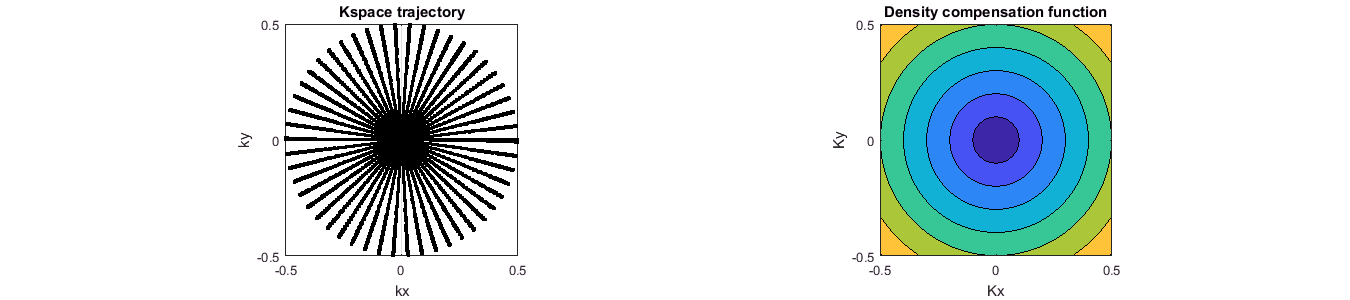

% First obtain the k-space trajectory and the corresponding density compensation function and check how it looks
angles=0:2*pi/(M*pi/2/1-1):2*pi;    % Radial angles
kspace_coords=radial_trajectory(angles,M);
density_weights=radial_weights(kspace_coords);

% Visualization
figure,subplot(121);scatter(matrix_to_vec(real(kspace_coords(:,1:round(M/32):end))),matrix_to_vec(imag(kspace_coords(:,1:round(M/32):end))),4,'k');box on;grid on;xlabel('kx');ylabel('ky');axis square;title('Kspace trajectory')
subplot(122);interpolant=scatteredInterpolant(real(kspace_coords(:)),imag(kspace_coords(:)),density_weights(:));
[xx,yy]=meshgrid(linspace(-.5,.5,M));intensity_interp=interpolant(xx,yy);
contourf(xx,yy,intensity_interp);xlabel('Kx');ylabel('Ky');title('Density compensation function');axis square;set(gcf,'Position',[0 0 1350 300]);

From the k-space trajectory plot you can observe that more samples are taken in the center of k-space then in the outskirts. If we then perform estimation of this sampling density we can get the corresponding contour plot (figure right). The more blue-ish indicates the higher density. What we then do is we multiply the interpolated k-space with the inverse of this density function to compensation for the difference in sampling density.

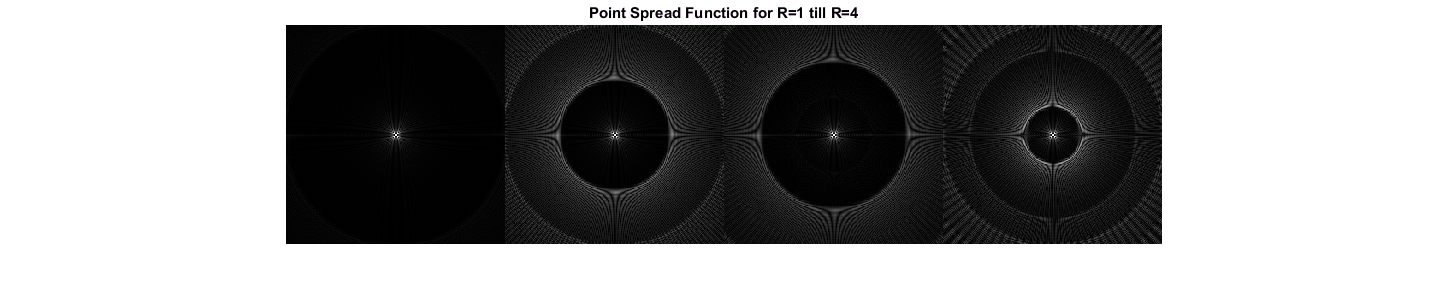

% Lets examine the point spread function (PSF) for a couple of undersampled radial acquisitions. 
% Dont bother about the syntax for now, only the result is important.
for Rn=1:4                   % Undersampling factor
    angles=0:2*pi/(M*pi/2/Rn-1):2*pi;
    kspace_coords=radial_trajectory(angles,M);
    density_weights=radial_weights(kspace_coords);
    W=DCF(density_weights); % density operator
    F=NUFFT(kspace_coords,[M M 1],[M size(kspace_coords,2) 1]); % Fourier operator
    K_psf=ones(size(kspace_coords));
    I_psf(:,:,Rn)=F'*(W*(K_psf));  % 2D Fast inverse Fourier Transform
    I_psf(:,:,Rn)=I_psf(:,:,Rn)/max(max(abs(I_psf(:,:,Rn))));
end

% Visualization
figure,imshow3(log(abs(I_psf)+1),[0 0.05],[1 4]);
set(gcf,'Position',[0 0 1450 300]);
title('Point Spread Function for R=1 till R=4');

You can observe that the energy gets folded over to a lot of pixels, even for the R=1 case! If we follow the same approach for the Cartesian sampling case, we will have to get the coil sensitivities from all those pixel positions and invert the $S^H S$ matrix which will have size of M^4 and we have to do this for every pixel! This is computionally too expensive and thats why we do not do it this way. You can also observe that when you increase the undersampling you see more and more pixels getting involved in the folding process, untill at a certain point the energy gets distributed over all the pixels. 

## Define radial trajectory, weights and NUFFT operators for the current undersampled case

In practice we like to define the operations such as applying the density compensation function, performing the non-uniform fast Fourier transform and multiplying the images with the coil sensitivity maps as operators in matlab. This simply means that we for each operation define a seperate class which replaces the Matlab function " * " with the defined operator. This makes it much easier to use in an iterative scheme where you have to perform the operations multiple times. First we define the radial angles, corresonding kspace trajectory and density weights and use these to create the operators.

% Define the radial angles, uniformly spaced 
angles=0:2*pi/(M*pi/2/R-1):2*pi; % [radians]

% Get the corresponding k-space trajectory
kspace_coords=radial_trajectory(angles,M);

% Get the corresponding density
density_weights=radial_weights(kspace_coords);

% Define the coil operator, fourier transform and density operator
W=DCF(density_weights); % density operator
S=CC(csm);      % Sense operator
F=NUFFT(kspace_coords,[M M NC],[M size(kspace_coords,2) NC]); % Fourier operator

Now we have our operators W,S and F with corresponding adjoint functions S' and F'. In words the W operator applies the density function on k-space data. The S operator takes all the coil images and combines them using the coil sensitivity maps. The S' (S-adjoint) operator takes the combined image and splits them into the uncombined coil images. The F operator takes an image, performs a fast Fourier transform and interpolates the k-space onto the desired non-Cartesian coordinates. The F' (F-adjoint) operator takes the non-Cartesian k-space coordinates, interpolates them onto a Cartesian grid and performs a fast Fourier transform. 

## Lets mimic a simplified version of the MR experiment!

Now that we have our operators that mimic the processes that happen at the scanner we can simulation the acquisition.  

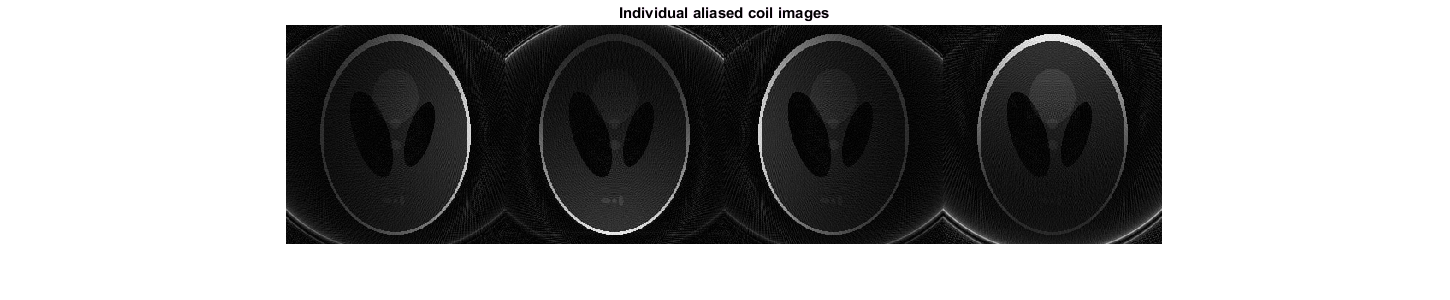

% We take our phantom image (x_true), multiply it with the coil sensitivity maps (S operator) and subsequently perform a Fourier transform (F operator).
y=F*(S'*x_true);   % y = measured k-space data

% Lets mimic real-live conditions which include noise on the measurements
% First define a function to add gaussian complex noise
add_noise=@(x,lvl)(x+lvl*randn(size(x))+1j*lvl*randn(size(x)));

% Add noise to our measurements "y"
y=add_noise(y/max(abs(y(:))),noise_sampling);

% Add noise to our measured coil sensitivity maps
csm=add_noise(csm,noise_csm);

% Perform an inverse nufft on the undersampled and noisy data
x_aliased=F'*(W*y); % This mimics the conventional reconsturction process

% Visualization
figure(3),imshow3(abs(cat(3,x_aliased/max(abs(x_aliased(:))))),[],[1 NC]);
set(gcf,'Position',[0 0 1450 300]);
title('Individual aliased coil images');

Now lets examine the individual aliased coil images. You can clearly observe that each receiver exhibits the different spatial sensitivities. In addition you can also observe the aliasing circle that we observed in the point spread functions.

## Lets perform the iterative sense recon for radial sampling

So instead of the direct inversion we discussed in the previous demo, we apply the generalized SENSE formulation that aims to minimize the following cost functional: ${\left\|\mathrm{FS'}\text{ }\mathbf{x}-\mathbf{y}\right\|}^2$. Note that we ignored the density estimation function for now.

        **x** = our current coil combined image estimate with size $\left\lbrack M\text{ }x\text{ }M\right\rbrack$ 

        **y** = the measured k-space data $\left\lbrack \mathrm{samples}\text{ }\text{ }\mathrm{nlines}\text{ }\mathrm{ncoils}\right\rbrack$

        F = Fourier transform operator 

        S = Coil sensitivity map operator

Intuitively this can be explained as we try to find the best image estimate **x**, that when used to simulate the acquisition results into the data that we measured (**y**). The simulating the data part can be described by $\text{FS'}\text{ }\mathbf{x}$. How to solve this is more an optimization theory problem, there are plenty ways to do this but the theory is out of scope for this demo.

What we do to solve this, for the current implementation, is we have to define a function handle in matlab that performs the forward operation and adjoint operation. Forward: take our current coil combined image estimate --> apply the coil sensitivities --> and do a fourier transform to mimic the k-space sampling ($\left.\mathrm{FS'}\text{ }\mathbf{x}\right)$. Adjoint: take the multi-coil k-space data, do an inverse Fourier transform and apply the coil sensitivities to spread the data across the receivers $\left(\mathrm{SF'}\text{ }\mathbf{y}\right)$. This is performed in the file iterative_sense.m.

Now we create a struct (params) that contains all the information to do the steps described above. And then we send this to the Matlab lsqr function. This is all we need to solve a L2-norm cost function, i.e. a least squares problem! We don't need to have any knowledge about the problem, as long as we can define the forward and adjoint operation and know that the problem is linear and convex. The code to perform the forward and adjoint operation is covered in iterative_sense.m.

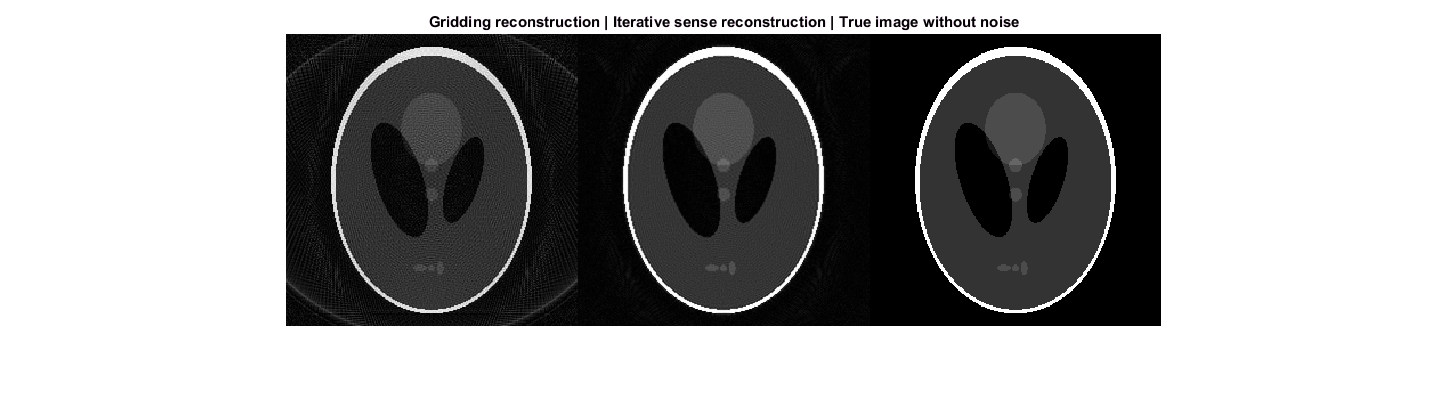

% Generate the structure to send to LSQR
params={};
params.S=S;                    % Sensitivity operator
params.F=F;                    % Fourier operator
params.W=DCF(sqrt(density_weights));   % Density operator
params.Id=size(csm);           % Image dimensions
params.Kd=size(y);             % K-space dimensions
params.y=params.W*y;           % Measured k-space data

% Send the struct to the matlab solver (lsqr)
func=@(x,tr) iterative_sense(x,params,tr);
[recon,~,~,~,~,~]=lsqr(func,params.y(:),1E-12,10);
x_recon=reshape(recon,params.Id(1:2));

% Visualization
tmp=S*x_aliased;
figure(4);
imshow3(cat(3,abs(tmp)/max(abs(tmp(:))),abs(x_recon)/prctile(abs(x_recon(:)),97.5),x_true),[0 1],[1 3]); 
set(gcf,'Position',[0 0 1450 400]);
title('Gridding reconstruction | Iterative sense reconstruction | True image without noise');

## Can we also use the same strategy for Cartesian sampling?

Lets try: we have to define a different k-space trajectory, fill the density weights with all ones and we have to replace the Fourier operator with the new trajectory. We still use the NUFFT for sake of simplicity, but this could also be done with a 2D fast Fourier transform.

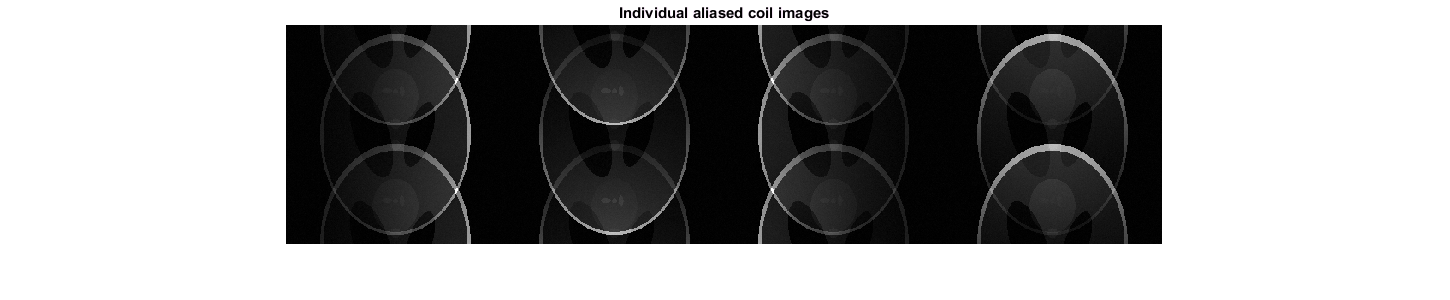

% New Cartesian k-space trajectory
ky=(sort([floor(M/2)-R+1:-R:1 floor(M/2)+1:R:M])-(M/2+1))/M;
kx=(sort([floor(M/2)-1+1:-1:1 floor(M/2)+1:1:M])-(M/2+1))/M;
[kx,ky]=meshgrid(kx,ky);
kspace_coords=permute(ky+1j*kx,[2 1]);

% New fourier operator
F=NUFFT(kspace_coords,[M M NC],[M size(kspace_coords,2) NC]);

% New density operator
W=DCF(ones(size(kspace_coords)));

% Mimic the kspace sampling process
y=F*(S'*x_true);   % y = measured k-space data

% Add noise to our measurements "y"
y=add_noise(y/max(abs(y(:))),noise_sampling);

% Conventional reconstruction process
x_aliased=F'*(W*y); 

% Visualization
figure(3),imshow3(abs(cat(3,x_aliased/max(abs(x_aliased(:))))),[],[1 NC]);
set(gcf,'Position',[0 0 1450 300]);
title('Individual aliased coil images');

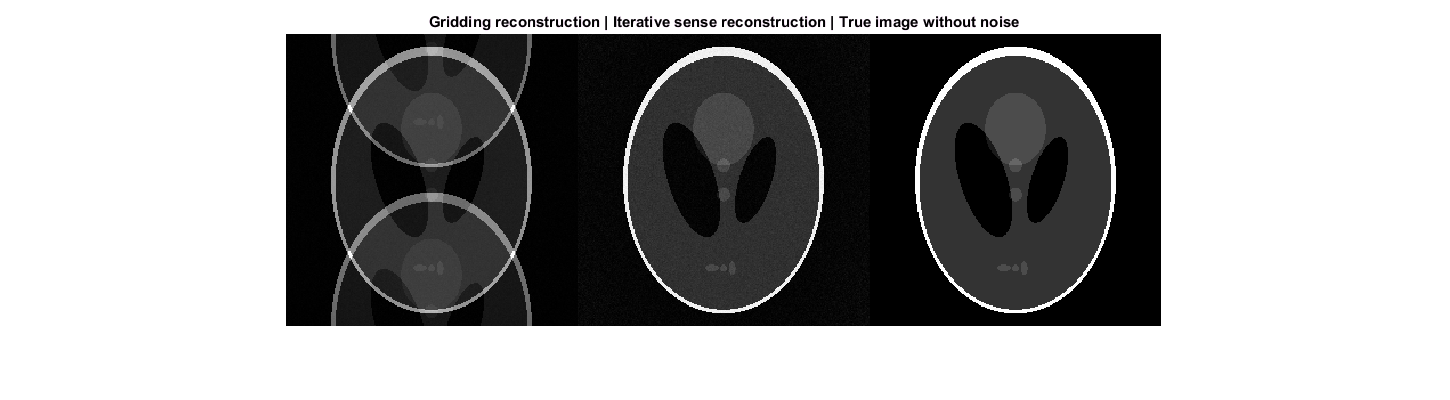

% Generate the structure to send to matlabs LSQR
params={};
params.S=S;                    % Sensitivity operator
params.F=F;                    % Fourier operator
params.W=W;                    % Density operator
params.Id=size(csm);           % Image dimensions
params.Kd=size(y);             % K-space dimensions
params.y=params.W*y;           % Measured k-space data

% Send the struct to the matlab solver (lsqr)
func=@(x,tr) iterative_sense(x,params,tr);
[recon,~,~,~,~,~]=lsqr(func,params.y(:),1E-12,10);
x_recon=reshape(recon,params.Id(1:2));

% Visualization
tmp=S*x_aliased;
figure(4);
imshow3(cat(3,abs(tmp)/max(abs(tmp(:))),abs(x_recon)/max(abs(x_recon(:))),x_true),[],[1 3]); 
set(gcf,'Position',[0 0 1450 400]);
title('Gridding reconstruction | Iterative sense reconstruction | True image without noise');

So the answer obviously is yes, you can also do Cartesian SENSE with this general iterative framework. However for Cartesian sampling it is computationally much more expensive then inverting the point spread functions as we generally do for Cartesian sampling.

% END